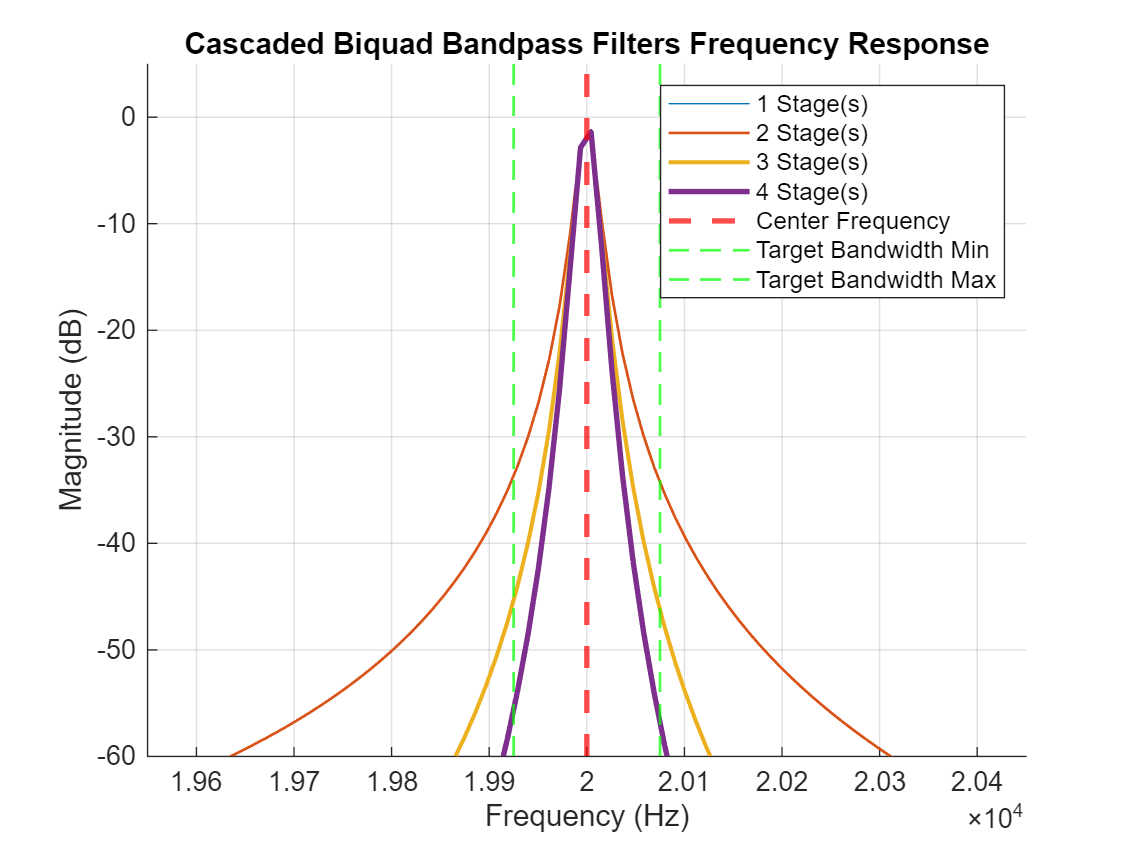

% MATLAB script to simulate and plot biquad bandpass filter responses
clear; clc;

% Filter parameters
fs = 44100;            % Sampling rate in Hz
fc = 20000;            % Center frequency in Hz
bw = 150;              % Bandwidth in Hz
Q_total = fc / bw;     % Total quality factor

% Frequency vector for response analysis
[H, f] = deal([]);
freq = linspace(0, fs/2, 2048);

% Loop through 1 to 4 stages
figure;
hold on;
colors = lines(4);
for stages = 1:4
    Q_stage = Q_total / sqrt(stages); % Adjusted Q per stage
    
    % Get biquad coefficients for one stage
    w0 = 2 * pi * fc / fs;
    alpha = sin(w0) / (2 * Q_stage);
    
    b = [alpha, 0, -alpha];
    a = [1 + alpha, -2*cos(w0), 1 - alpha];
    b = b / (1 + alpha); % Normalize
    a = a / (1 + alpha); % Normalize

    % Cascade the same stage multiple times
    sos = repmat([b, a], stages, 1);
    
    % Frequency response of the cascaded filter
    [h, f_resp] = freqz(sos, 2048, fs);
    
    % Plot magnitude response
    plot(f_resp, 20*log10(abs(h)), 'DisplayName', sprintf('%d Stage(s)', stages), ...
         'Color', colors(stages,:), "LineWidth", stages/2);
end

grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Cascaded Biquad Bandpass Filters Frequency Response');
legend("Location", "northeast");
xline(fc, "r--", "LineWidth", 2, "DisplayName", "Center Frequency")
xline(fc-bw/2, "g--", "LineWidth", 1, "DisplayName", "Target Bandwidth Min")
xline(fc+bw/2, "g--", "LineWidth", 1, "DisplayName", "Target Bandwidth Max")
xlim([fc - (bw*3), fc + (bw*3)]); % Zoom in around center frequency
ylim([-60 5]);